clear
close all
clc

%Load_data
ref=load("Results\reftrack.mat");
cons=load("Results\constraintsunit.mat");
C_hor=load("Results\C_horizon.mat");
R_hor=load("Results\R_horizon.mat");
%Global params
parameters=cons.parameters;
obstacle=cons.obstacle;
lanewidth=cons.lanewidth;
lanes=cons.lanes;
T=cons.T;

Results 1.1: Car path for constraint scheme, 

Results 1.2 yRef vs X

scheme A

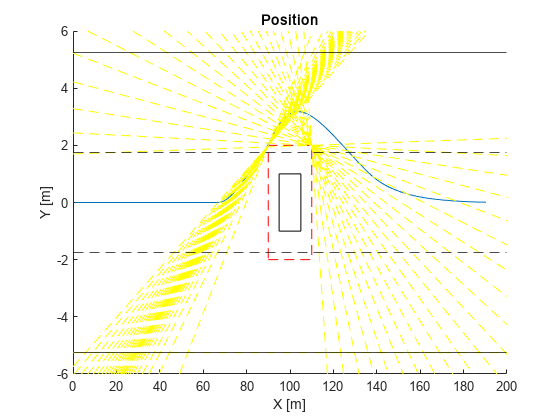

figure
hold on
plot(cons.states(1,:),cons.states(2,:))
% 
% % Define obstacle vertices
% obstacle_vertices = [obstacle.fl; obstacle.fr; obstacle.rr; obstacle.rl];
% 
% % Plot obstacle
% rectangle('Faces', [1 2 3 4], 'Vertices', obstacle_vertices, 'FaceColor', 'red')
rectangle(Position=[obstacle.rrX,obstacle.rrY,obstacle.Length,obstacle.Width])
rectangle('Position',[obstacle.rrSafeX,obstacle.rrSafeY,obstacle.Length+2*obstacle.safeDistanceX,obstacle.Width+2*obstacle.safeDistanceY],'LineStyle','--',EdgeColor='red')
yline(lanewidth/2,'black--')
yline(-lanewidth/2,'black--')
yline(-lanewidth*lanes/2,'black')
yline(lanewidth*lanes/2,'black')
% xlim([0 500])
ylabel('Y [m]')
xlabel('X [m]') 
title('Position')
for i=1:length(cons.slopes)
    X=[0;50;200];
    Y=cons.slopes(i)*X+cons.intercepts(i);
    line(X,Y,'LineStyle','--','Color','yellow')
end
ylim([-6 6])
xlim([0 200])
hold off

Results 1.2: Comparison between both tracking schemes

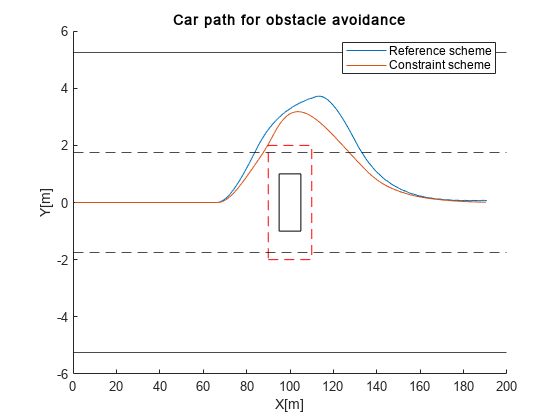

figure
hold on
plot(ref.states(1,:),ref.states(2,:))
plot(cons.states(1,:),cons.states(2,:))


rectangle(Position=[obstacle.rrX,obstacle.rrY,obstacle.Length,obstacle.Width])
rectangle('Position',[obstacle.rrSafeX,obstacle.rrSafeY,obstacle.Length+2*obstacle.safeDistanceX,obstacle.Width+2*obstacle.safeDistanceY],'LineStyle','--','EdgeColor','red')
yline(lanewidth/2,'black--')
yline(-lanewidth/2,'black--')
yline(-lanewidth*lanes/2,'black')
yline(lanewidth*lanes/2,'black')
% xlim([0 500])
ylabel('Y[m]')
xlabel('X[m]') 
title('Car path for obstacle avoidance')
ylim([-6 6])
xlim([0 200])
legend('Reference scheme','Constraint scheme','','','','')
hold off

Results 1.3: State and input evolution for both schemes (Detection toevoegen)

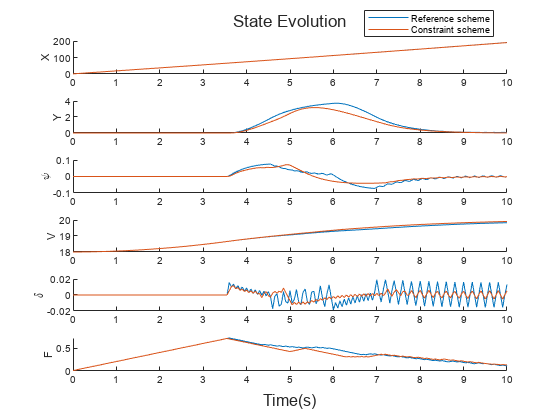

fig1=tiledlayout(6,1);;
fig1.Title.String='State Evolution';
% title(fig1, "State evolution")
ax1=nexttile;
hold on
plot(ax1,T,ref.states(1,:))
plot(ax1,T,cons.states(1,:))
hold off
ylabel('X')
ax2=nexttile;
hold on
plot(T,ref.states(2,:))
plot(T,cons.states(2,:))
hold off
ylabel('Y')
ax3=nexttile;
hold on

plot(T,ref.states(3,:))
plot(T,cons.states(3,:))
hold off
ylabel('\psi')
ax4=nexttile;
hold on
plot(T,cons.states(4,:))
plot(T,ref.states(4,:))
hold off
ylabel('V')
ax5=nexttile;
hold on

plot(T,ref.inputs(1,:))
plot(T,cons.inputs(1,:))
hold off
ylabel('\delta')
ax6=nexttile;
hold on

plot(T,ref.inputs(2,:))
plot(T,cons.inputs(2,:))
hold off
ylabel('F')
linkaxes([ax1,ax2,ax3,ax4,ax5,ax6],'x')
xlabel(fig1,'Time(s)')
fig1.TileSpacing="compact";
% axes 1
xlim([0.00 10.00])
legend('Reference scheme','Constraint scheme',"Position", [0.65,0.9127,0.23214,0.063095])

Results 1.4: MPC cost for both schemes

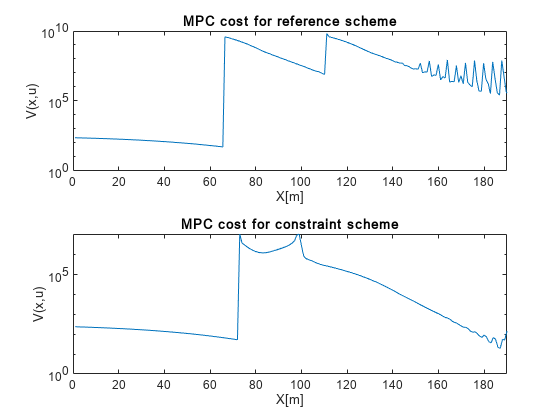

figure;
tiledlayout('flow');
nexttile;

semilogy(ref.states(1,:),ref.costs)

title("MPC cost for reference scheme")
xlabel('X[m]')
ylabel('V(x,u)')
xlim([0 190])
% plot(ref.states(1,:),ref.costs)
nexttile;

% plot(cons.costs)
semilogy(cons.costs)
title("MPC cost for constraint scheme")
xlabel('X[m]')
ylabel('V(x,u)')
xlim([0 190])

% ylim([0 100])

Results 2: plots for varying control horizons

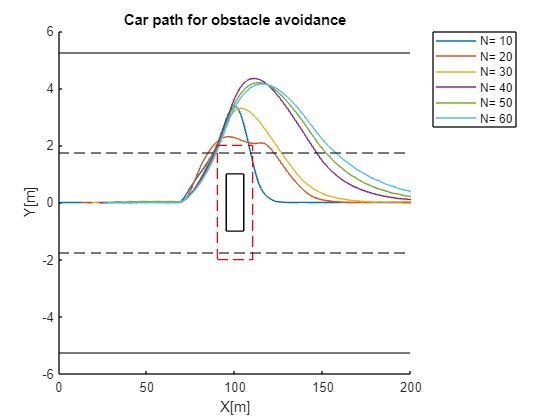

figure
hold on
for i=1:length(C_hor.predN)
    plot(squeeze(C_hor.statesN(i,1,:)),squeeze(C_hor.statesN(i,2,:)),'DisplayName',"N= "+string(C_hor.predN(i)))
end


rectangle(Position=[obstacle.rrX,obstacle.rrY,obstacle.Length,obstacle.Width])
rectangle('Position',[obstacle.rrSafeX,obstacle.rrSafeY,obstacle.Length+2*obstacle.safeDistanceX,obstacle.Width+2*obstacle.safeDistanceY],'LineStyle','--','EdgeColor','red')
yline(lanewidth/2,'black--')
yline(-lanewidth/2,'black--')
yline(-lanewidth*lanes/2,'black')
yline(lanewidth*lanes/2,'black')
% xlim([0 500])
ylabel('Y[m]')
xlabel('X[m]') 
title('Car path for obstacle avoidance')
ylim([-6 6])
xlim([0 200])
lgd=legend('Location','bestoutside');
lgd.String(7:end)=[];
% legend('Reference scheme','Constraint scheme','','','','')
hold off